# Desmooth Returns

## **Hedge fund smooths returns**

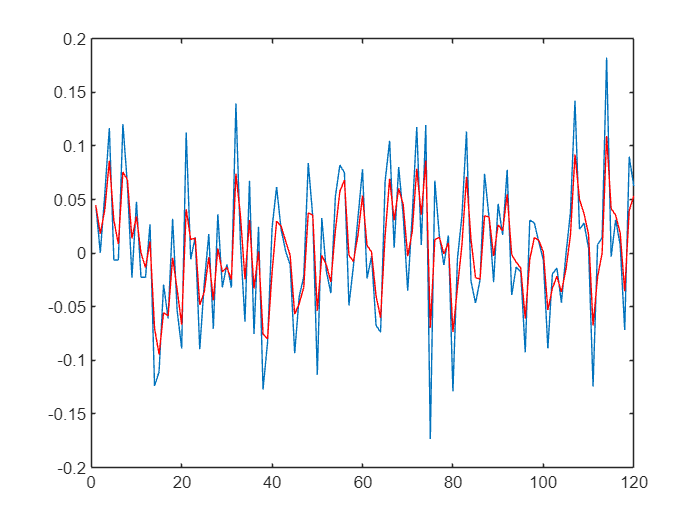

[true_returns,rSmooth] = pyrunfile('genSmoothReturns.py', ["true_returns", "smoothed_returns"]);
rActual = double(true_returns);
rSmooth = double(rSmooth)';
figure;
plot(rActual)
hold on
plot(rSmooth,'r')

## **Unsmooth Returns by Estimating the AR coefficient for Smoothing (Econometric Modeling Method)**

n_months = length(rSmooth);

% Fit an AR model to the smoothed returns using the Econometrics Toolbox
model_order = 1; % Choose the order of the AR model
Mdl = arima(model_order, 0, 0); % AR(1) model
EstMdl = estimate(Mdl, rSmooth)

 
    ARIMA(1,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0029212      0.0035676       0.81881         0.41289
    AR{1}         0.38673       0.094678        4.0847      4.4143e-05
    Variance    0.0015021     0.00019444        7.7252      1.1166e-14



EstMdl =   arima with properties:

     Description: "ARIMA(1,0,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               D: 0
               Q: 0
        Constant: 0.00292118
              AR: {0.386728} at lag [1]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.0015021

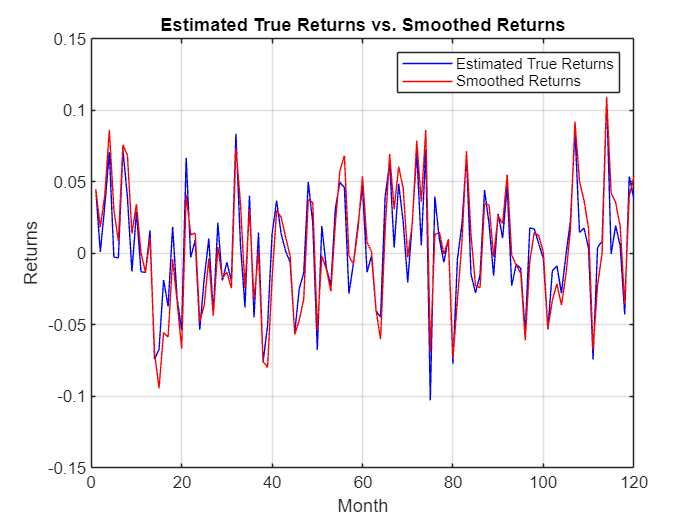


% Extract AR coefficients
a1_Econ = cell2mat(EstMdl.AR);

% Initialize the array for estimated true returns
estimated_true_returns = zeros(n_months, 1);

% Initialize the first estimated true return
estimated_true_returns(1) = rSmooth(1);

% Unsmooth the returns using the AR model
for t = 2:n_months
    estimated_true_returns(t) = rSmooth(t) - a1_Econ * rSmooth(t-1);
end

% Plot the results
figure;
plot(1:n_months, estimated_true_returns, 'b', 'DisplayName', 'Estimated True Returns');
hold on;
plot(1:n_months, rSmooth, 'r', 'DisplayName', 'Smoothed Returns');
legend;
title('Estimated True Returns vs. Smoothed Returns');
xlabel('Month');
ylabel('Returns');
grid on;
hold off;

## **Unsmooth Returns by Estimating the AR coefficient for Smoothing (Signal Processing Method)**

% Load the smoothed returns data
n_months = length(rSmooth);

% Fit an AR model to the smoothed returns
model_order = 1; % Choose the order of the AR model
model = ar(rSmooth, model_order)

model =
Discrete-time AR model: A(z)y(t) = e(t)
  A(z) = 1 - 0.3865 z^-1               
                                       
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1
   Number of free coefficients: 1
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                     
Estimated using AR ('fb/now') on time domain data "rSmooth".
Fit to estimation data: 7.698%                              
FPE: 0.001524, MSE: 0.001499                                
 
Model Properties


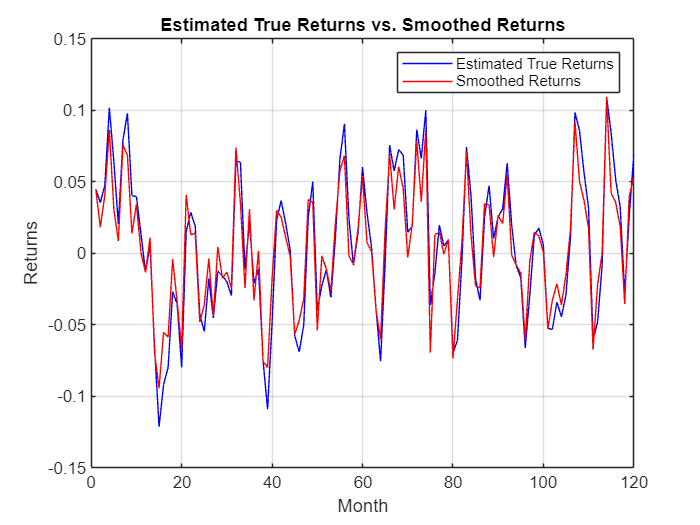


% Extract AR coefficients
coefficients = model.A;
a1 = coefficients(2); % First AR coefficient (assumes AR(1) model)

% Initialize the array for estimated true returns
estimated_true_returns = zeros(n_months, 1);

% Initialize the first estimated true return
estimated_true_returns(1) = rSmooth(1);

% Unsmooth the returns using the AR model
for t = 2:n_months
    estimated_true_returns(t) = rSmooth(t) - a1 * rSmooth(t-1);
end

% Plot the results
figure;
plot(1:n_months, estimated_true_returns, 'b', 'DisplayName', 'Estimated True Returns');
hold on;
plot(1:n_months, rSmooth, 'r', 'DisplayName', 'Smoothed Returns');
legend;
title('Estimated True Returns vs. Smoothed Returns');
xlabel('Month');
ylabel('Returns');
grid on;
hold off;